# Lecture 7: Stability, P/PD controllers and bode plots

- P controller & stability using pole locations

- PD controller & stability using pole locations

- Bode plot basics

Consider a printer head that is designed to move back and forth in a line along a desired trajectory. 

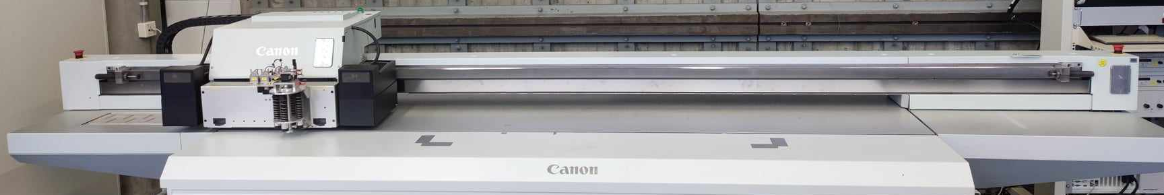

A simple model of this system is a free mass controlled with a servo force $u\left(t\right)$.

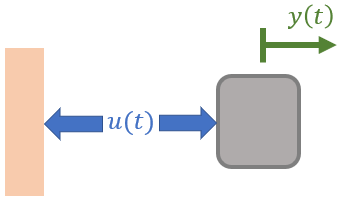

A sensor is used to measure the position of the mass $y\left(t\right)$. That signal is compared to a desired reference position $r\left(t\right)$. The difference between these signals is the error $e\left(t\right)$ which is fed into a microcontroller $C\left(s\right)$ which commands an actuator to provide a servo force $u\left(t\right)$. 

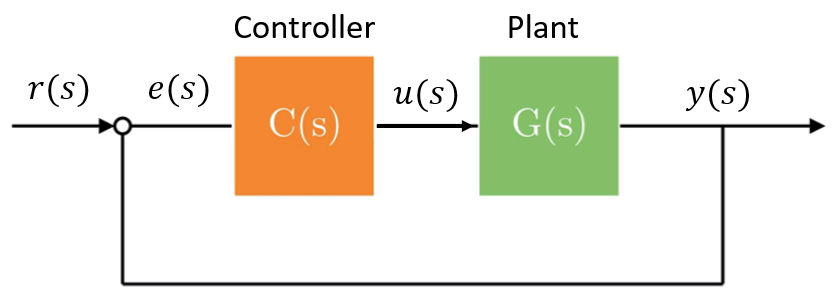

## Plant

The transfer function of the plant $G\left(s\right)$ is found from Lagrange Equations of Motion and applying a Laplace transform.


$$m\ddot{y} =u\left(t\right)$$



$${\mathrm{ms}}^2 y\left(s\right)=u\left(s\right)$$



$$\frac{y\left(s\right)}{u\left(s\right)}=G\left(s\right)=\frac{1}{{\mathrm{ms}}^{2\;} }$$


## Closed loop

The closed loop transfer function is $\frac{y\left(s\right)}{r\left(s\right)}=T\left(s\right)$ which can be written in terms of the open-loop TF $\frac{y\left(s\right)}{u\left(s\right)}=L\left(s\right)$.


$$L\left(s\right)=C\left(s\right)G\left(s\right)$$



$$T\left(s\right)=\frac{L\left(s\right)}{1+L\left(s\right)}$$


## Stability

- A system is stable if **all** of the poles (roots of the denominator of TF) are in the left half plane (LHP) $\textrm{Re}\left(p_i \right)<0$.

- A system is unstable if **any** pole is in the right half plane (RHP) $\textrm{Re}\left(p_i \right)>0$. 

- If **all** of the poles happen to lie perfectly on the imaginary axis $\textrm{Re}\left(p_i \right)=0$ then the system will vibrate forever without decaying to 0 or exploding to infinity.  

## P controller

A P-controller has the form $C\left(s\right)=P$. Let's see the influences different P gains $P=10$, $P=100$, and $P=1000$ have on the closed-loop system $T\left(s\right)$. We'll first see this in the time domain using step $r\left(t\right)=1\left(t\right)$ and impulse $r\left(t\right)=\delta \;\left(t\right)$.

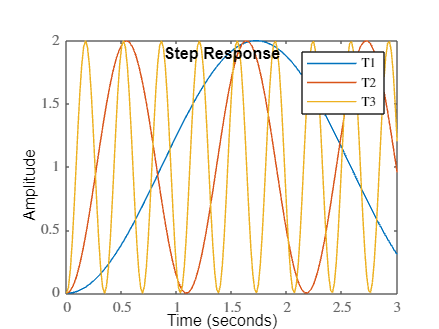

clc; clear all; close all;

m = 3;      % kg

s = tf('s');
G = 1/(m*s^2);
% P Controllers
C1 = 10;
C2 = 100;
C3 = 1000;
% Open loop
L1 = C1*G;
L2 = C2*G;
L3 = C3*G;
% Closed Loop
T1 = minreal(L1/(1+L1));
T2 = minreal(L2/(1+L2));
T3 = minreal(L3/(1+L3));

%step response: y(t) due to u(t) = 1(t)
step(T1,3)
hold on
step(T2,3)
hold on
step(T3,3)
legend
hold off

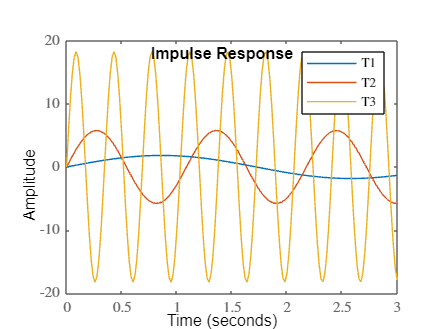


%impulse response: y(t) due to u(t) = delta(t)
impulse(T1,3)
hold on
impulse(T2,3)
hold on
impulse(T3,3)
legend
hold off


% Check stability
T1_poles = pole(T1)

T1_poles =    0.0000 + 1.8257i
   0.0000 - 1.8257i


T2_poles = pole(T2)

T2_poles =    0.0000 + 5.7735i
   0.0000 - 5.7735i


T3_poles = pole(T3)

T3_poles =    0.0000 +18.2574i
   0.0000 -18.2574i



clear C1 C2 C3 L1 L2 L3 T1 T2 T3

Since the real parts of the poles are 0 there will be perfect (undamped) oscillation. P-gain just increases the frequency of the oscillation. The P-gain acts like a spring.

## PD controller

There are many forms of PD-controllers. The simplest one is $C\left(s\right)=P+\textrm{Ds}$. Let's see the influences of different D gains $D=0\ldotp 1$, $D=1$, and $D=10$ have on the closed-loop system $T\left(s\right)$. We'll first see this in the time domain using step $r\left(t\right)=1\left(t\right)$ and impulse $r\left(t\right)=\delta \;\left(t\right)$.

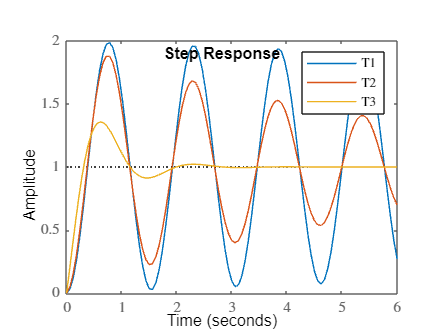

P = 50;
D1 = 0.1;
D2 = 1;
D3 = 10;

% PD Controllers
C1 = P+D1*s;
C2 = P+D2*s;
C3 = P+D3*s;
% Open loop
L1 = C1*G;
L2 = C2*G;
L3 = C3*G;
% Closed Loop
T1 = minreal(L1/(1+L1));
T2 = minreal(L2/(1+L2));
T3 = minreal(L3/(1+L3));

%step response: y(t) due to u(t) = 1(t)
step(T1,6)
hold on
step(T2,6)
hold on
step(T3,6)
legend
hold off

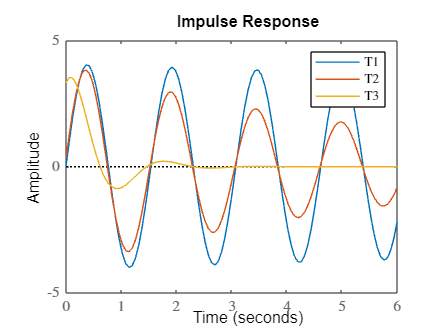


%impulse response: y(t) due to u(t) = delta(t)
impulse(T1,6)
hold on
impulse(T2,6)
hold on
impulse(T3,6)
legend
hold off


% Check stability
T1_poles = pole(T1)

T1_poles =   -0.0167 + 4.0824i
  -0.0167 - 4.0824i


T2_poles = pole(T2)

T2_poles =   -0.1667 + 4.0791i
  -0.1667 - 4.0791i


T3_poles = pole(T3)

T3_poles =   -1.6667 + 3.7268i
  -1.6667 - 3.7268i


Since all of the real parts of the poles are <0 then the system is stable and so vibrations will damp out. Increasing D-gain damps out vibration faster. The D-gain acts like a damper.

## Final value

The final value of the response can be found using this formula. Only works if $Y\left(s\right)$ is stable.


$$y\left(\infty \right)=\lim_{s\to 0} Y\left(s\right)\times s$$


% Final value of step response (r(s)=1/s)
y1_step_FV = evalfr(T1,0)

y1_step_FV = 1.0000

y2_step_FV = evalfr(T2,0)

y2_step_FV = 1.0000

y3_step_FV = evalfr(T3,0)

y3_step_FV = 1.0000


% Final value of impulse response (r(s)=1)
y1_imp_FV = evalfr(T1*s,0)

y1_imp_FV = 0

y2_imp_FV = evalfr(T2*s,0)

y2_imp_FV = 0

y3_imp_FV = evalfr(T3*s,0)

y3_imp_FV = 0

Hence this PD controller acts just like a spring mass damper system. The P-gain acts like a spring. The D-gain acts like a damper.

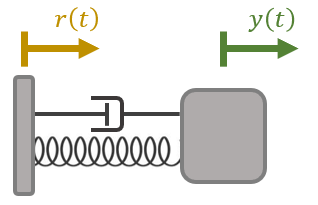

## Bode Plot Basics

A bode plot (=FRF) for the plant $G=\frac{1}{{\textrm{ms}}^2 }$, controller $C=50+10s$, open-loop $L=\textrm{CG}$ and closed-loop $T=\frac{L}{1+L}$ is shown. As studied in M3, the bode plot displays the gain and phase of the 'steady state' behavior $\left(s=j\omega \right)$. 

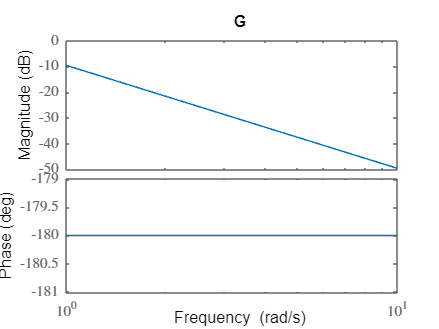

bode(G)
title('G')

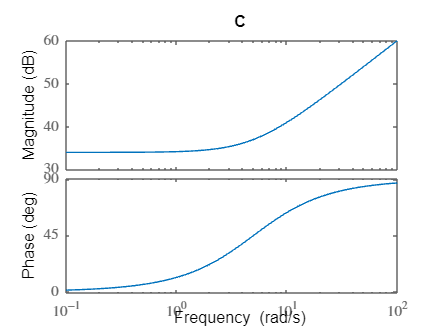

bode(C3)
title('C')

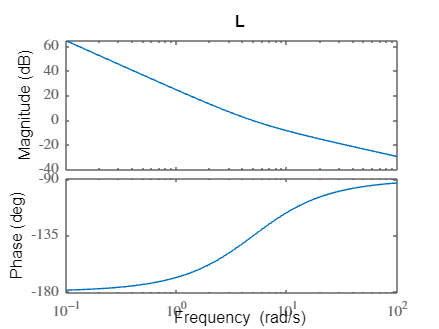

bode(L3)
title('L')

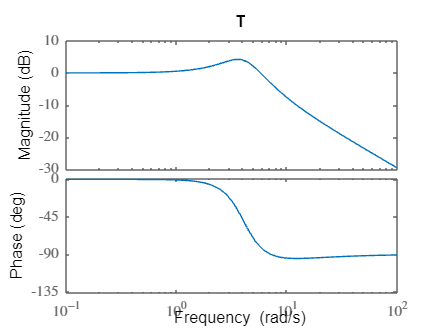

bode(T3)
title('T')

*The bode plot showing *$L\left(j\omega \;\right)$* is crucial for quantifying closed loop stability, robustness and loop shaping and will be discussed further in future lectures.* For now notice the 'bode gain-phase relationship':

- $G\left(j\omega \;\right)$ shows a '-2' slope and -180 degrees phase

- $C\left(j\omega \;\right)$ shows a '+1' slope and +90 degrees phase after the break frequency $\frac{50}{10}=5$ rad/s

Also notice that the closed-loop $T\left(j\omega \;\right)=0\;\textrm{dB}=1$ at low frequencies. This implies we have great reference tracking at low frequenices since $y=T\times r=r$. This is because the open-loop $L\left(j\omega \;\right)$has very high gain at low frequencies $T=\frac{L}{1+L}\approx \frac{\infty }{1+\infty \;}=1$